# Algorítimo de estabilização de robô humanoide

O objetivo desse projeto e gerar um algorítimo capaz de reequilibrar um robô humanoide que sobreu uma força qualquer. Para essa análise será considerado somente o equilibrio no plano xz e o robô humanoide será simplificado pro um mecanismo plano de 4 barras representando o momento em que o robô está se equilibrando em um pé.

% === Parâmetros ===
clear; close all; clc;

% Comprimentos das barras 
P.lb = 0.050;        % solo -> tornozelo   (FIXA)            [m]
P.l1 = 0.120;        % tornozelo -> joelho                   [m]
P.l2 = 0.120;        % joelho -> quadril                     [m]
P.l3 = 0.140;        % quadril -> CM do tronco               [m]

% Massas 
P.mb = 0.200;        % pés + estrutura do tornozelo    (8 %) [kg]
P.m1 = 0.375;        % canelas, 2x                    (15 %) [kg]
P.m2 = 0.500;        % coxas, 2x                      (20 %) [kg]
P.m3 = 1.425;        % tronco + cabeça + braços       (57 %) [kg]

% Inércia em torno do CM de cada barra (barra delgada uniforme: m*L^2/12)
P.I1 = P.m1 * P.l1^2 / 12;   % canela
P.I2 = P.m2 * P.l2^2 / 12;   % coxa
P.I3 = P.m3 * P.l3^2 / 12;   % tronco

% Matriz de massa das 3 barras móveis, 9x9: (x, y, theta) por corpo.
P.M_mat = diag([P.m1 P.m1 P.I1   P.m2 P.m2 P.I2   P.m3 P.m3 P.I3]);

% Posição do CM de cada barra
P.cb = 0.50;         % barra fixa: aproximada como uniforme
P.c1 = 0.50;         % canela
P.c2 = 0.50;         % coxa
P.c3 = 0.50;         % tronco: barra uniforme, CM no meio de l3

% Base de apoio (pé) 
P.d_calcanhar = 0.045;   % para trás  (-x)                   [m]
P.d_ponta     = 0.075;   % para frente (+x)                  [m]

% Constantes
P.g = 9.81;              % gravidade                     [m/s^2]

% ACELERAÇÃO IMPOSTA AO CM 
P.ax = 1.20;              % [m/s²]  positivo = para a frente
P.ay = 0.00;              % [m/s²]  positivo = para cima

% Janela de tempo
P.dt = 0.001;             % passo                            [s]

% Atuador AX-12A
P.tau_max = 1.5;          % estol do AX-12A @ 12V   [N·m]

% Newton-Raphson
P.tol = 1e-10;
P.N   = 60;

% Alvo do controle: posição ideal do CM
P.x_alvo = 0.000;         % [m]
P.y_alvo = 0.400;         % [m]

% Variaveis simbólicas
syms theta_1 theta_2 theta_3 x_1 x_2 x_3 y_1 y_2 y_3 real
syms t real
syms f(t) g(t)   

q = [x_1; y_1; theta_1; x_2; y_2; theta_2; x_3; y_3; theta_3];

P.T_junta = [1 0 0; -1 1 0; 0 -1 1];   % absoluto -> junta

## Cinemática do sistema

primeiro vamos definir como calcular os angulos para o mecanismo permanecer na sua posição ideial. Para essa situação são tratadas seis restrições cinemáticas:


$$\phi_1 = \left[\begin{array}{c}
x_1 - \frac{l_1}{2}\cos \theta_1 \\
y_1 - l_b - \frac{l_1}{2}\sin \theta_1 \\
x_2 - l_1 \cos \theta_1 - \frac{l_2}{2}\cos \theta_2\\
y_2 - l_b - l_1 \sin \theta_1 - \frac{l_2}{2}\sin \theta_2\\
x_3 - l_1 \cos \theta_1 - l_2 \cos \theta_2 - \frac{l_3}{2}\cos \theta_3 \\
y_3 - l_b - l_1 \sin \theta_1 - l_2 \sin \theta_2 - \frac{l_3}{2}\sin \theta_3
\end{array}\right] = \mathbf{0}$$


E duas restrições diretoras , o tronco sempre deve estar ereto:


$$\phi_2 = \theta_3 - \pi/2$$


E o centro de massa deve estar sempre seguindo as fuções f e g:


$$\left[\begin{array}{c}
x_{cm} \\
y_{cm}
\end{array}\right]
=
\left[\begin{array}{c}
l_1 \cos\theta_1 + l_2 \cos\theta_2 + l_3 \cos\theta_3 \\
l_b + l_1 \sin\theta_1 + l_2 \sin\theta_2 + l_3 \sin\theta_3
\end{array}\right]
=
\left[\begin{array}{c}
f(t)\\
g(t)
\end{array}\right]$$



$$\phi_3
=
\left[\begin{array}{c}
x_{cm} - f(t)\\
y_{cm} - g(t)
\end{array}\right]
= 0$$


%% Definição simbólica das restrições

A = [0; P.lb];                    % pino do tornozelo = topo da barra fixa

% ── phi_1: vínculos de revolução (6 equações) ────────────────────────────
%  CM de cada barra = pino anterior + METADE do próprio comprimento
phi_1 = [ x_1 - ( A(1) + (P.l1/2)*cos(theta_1) )                                        ;
          y_1 - ( A(2) + (P.l1/2)*sin(theta_1) )                                        ;
          x_2 - ( A(1) + P.l1*cos(theta_1) + (P.l2/2)*cos(theta_2) )                    ;
          y_2 - ( A(2) + P.l1*sin(theta_1) + (P.l2/2)*sin(theta_2) )                    ;
          x_3 - ( A(1) + P.l1*cos(theta_1) + P.l2*cos(theta_2) + (P.l3/2)*cos(theta_3) );
          y_3 - ( A(2) + P.l1*sin(theta_1) + P.l2*sin(theta_2) + (P.l3/2)*sin(theta_3) )];

% phi_2: tronco ereto
phi_2 = theta_3 - pi/2;

% phi_3: CM segue a trajetória imposta
x_cm = P.l1*cos(theta_1) + P.l2*cos(theta_2) + P.l3*cos(theta_3);
y_cm = P.lb + P.l1*sin(theta_1) + P.l2*sin(theta_2) + P.l3*sin(theta_3);

phi_3 = [ x_cm - f(t) ;
          y_cm - g(t) ];

% Vetor completo
phi = [phi_1; phi_2; phi_3];
phi_q = simplify(jacobian(phi, q))

phi_t  = diff(phi, t);                 
nu     = -phi_t                        

## Cinemática

### Caso estático

Uma vez que essa análise será feitra agumas vezes definiuse uma função que faz essa mesma lógica para diferentes acelerações do centro de massa. Inicialmente vamos analisar o caso ideal: posição (0, 0.4) com o centro demassa parado em equilibrio

% Caso 1 — estático
f1 = P.x_alvo;   g1 = P.y_alvo;              

[Q1, ~, ~] = cinematica_cm(P, t, f1, g1, 0);
q_ideal = Q1(:,1);

fprintf('Postura ideal — absoluto: [%.2f %.2f %.2f]°\n', rad2deg(q_ideal([3 6 9])));
fprintf('junta:  [%.2f %.2f %.2f]°  (tornozelo, joelho, quadril)\n',rad2deg(P.T_junta * q_ideal([3 6 9])));

Vale resltar que este problema não está totalmente definido possuindo mais de uma solução que seria a figura simetrica a esta (com o joelho na esqueda) mas no mecanismo essa solução é descartada ao definir-se que o joelho não pode assumir angulos negativos e no algorítimo isso é corigido ao se colocar o valor de $\pi/2$ como chute inicial fazendo a método convergir para a solução com o joelho a direita

### Força imposta

consideremos agora que uma força desconhecida agiu no nosso mecanismo de forma a impor uma aceleração ao centro de massa e analisaremos como ele reagiria sem nenhuma intervenção.

% Caso 2 — força imposta
t_reac = 0.10;

f2 = P.x_alvo + 0.5*P.ax*t^2;
g2 = P.y_alvo + 0.5*P.ay*t^2;
tv2 = 0:P.dt:t_reac;


$$phi\_q = \begin{array}{l} \left(\begin{array}{ccccccccc} 1 & 0 & \frac{3\,\sin\left(\theta_{1}\right)}{50} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & -\frac{3\,\cos\left(\theta_{1}\right)}{50} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \sigma_{1} & 1 & 0 & \frac{3\,\sin\left(\theta_{2}\right)}{50} & 0 & 0 & 0\\ 0 & 0 & -\sigma_{4} & 0 & 1 & -\frac{3\,\cos\left(\theta_{2}\right)}{50} & 0 & 0 & 0\\ 0 & 0 & \sigma_{1} & 0 & 0 & \sigma_{2} & 1 & 0 & \frac{7\,\sin\left(\theta_{3}\right)}{100}\\ 0 & 0 & -\sigma_{4} & 0 & 0 & -\sigma_{3} & 0 & 1 & -\frac{7\,\cos\left(\theta_{3}\right)}{100}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & -\sigma_{1} & 0 & 0 & -\sigma_{2} & 0 & 0 & -\frac{7\,\sin\left(\theta_{3}\right)}{50}\\ 0 & 0 & \sigma_{4} & 0 & 0 & \sigma_{3} & 0 & 0 & \frac{7\,\cos\left(\theta_{3}\right)}{50} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\sin\left(\theta_{1}\right)}{25}\\ \sigma_{2}=\frac{3\,\sin\left(\theta_{2}\right)}{25}\\ \sigma_{3}=\frac{3\,\cos\left(\theta_{2}\right)}{25}\\ \sigma_{4}=\frac{3\,\cos\left(\theta_{1}\right)}{25} \end{array}$$

[Q2, DQ2, DDQ2] = cinematica_cm(P, t, f2, g2, tv2, q_ideal)

### Movimento corrigido

A pós sofre a força considera-se que existe um tempo de reação e após o mecanismo passa a atuar realizando uma força contraria que anula o efeito da pertubação e retorna o mecanismo para a posição ideal.

Para isso vamos definir as funções f e g deve-se resolver o **problema de valor de contorno** por trás da trajetória quíntica: dado que temos a  posição, velocidade, aceleração atual (após a pertubação) e onde quer chegar (ideal), formando então o único polinômio de 5º grau que passa exatamente por essas 6 condições.

%% Caso 3 — correção
pos1  = [P.x_alvo; P.y_alvo] + 0.5*[P.ax;P.ay]*t_reac^2;    % posição do CM em t_reac

$$nu = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ \frac{\partial }{\partial t}f\left(t\right)\\ \frac{\partial }{\partial t}g\left(t\right) \end{array}\right)$$

vel1  = [P.ax;P.ay]*t_reac;                                 % velocidade do CM em t_reac
acc1  = [P.ax;P.ay];                                        % aceleração do CM em t_reac
alvo0 = [P.x_alvo; P.y_alvo];
T_cor = 0.10;

Cx = quintico_coef(pos1(1), vel1(1), acc1(1), alvo0(1), 0, 0, T_cor);
Cy = quintico_coef(pos1(2), vel1(2), acc1(2), alvo0(2), 0, 0, T_cor);

syms s real                        % tempo LOCAL do retorno (s = t_global - t_reac)
f3 = Cx(1) + Cx(2)*s + Cx(3)*s^2 + Cx(4)*s^3 + Cx(5)*s^4 + Cx(6)*s^5;
g3 = Cy(1) + Cy(2)*s + Cy(3)*s^2 + Cy(4)*s^3 + Cy(5)*s^4 + Cy(6)*s^5;

tv3_local = 0:P.dt:T_cor;
[Q3, ~, DDQ3] = cinematica_cm(P, s, f3, g3, tv3_local, Q2(:,end));

% Junta tudo numa linha do tempo só, para plotar/animar.
% tv2 termina exatamente em t_reac e tv3_local começa em 0, entao o instante
% da emenda apareceria repetido: descarta a 1a coluna do trecho de retorno.

tv3_global = t_reac + tv3_local;

Postura ideal — absoluto: [61.04 118.96 90.00]°


tv  = [tv2,   tv3_global(2:end)];

junta:  [61.04 57.91 -28.96]°  (tornozelo, joelho, quadril)


Q   = [Q2,    Q3(:,2:end)];
DDQ = [DDQ2,  DDQ3(:,2:end)];

fprintf('Recuperação: junta final = [%.2f %.2f %.2f]°  (alvo = postura ideal)\n', ...
        rad2deg(P.T_junta * Q([3 6 9], end)));

## Dinâmica

A principio o proplema estaria resolvido prorém na realidade fazendo a análise dinâmica percebe-se que não levou-se em consideração o limite de torque dos motores, impedindo a correção para pertubações maiores. Dessa forma voltamos a análise inicial mas agora considerando a dinâmica.

### Dinâmica estática


$$\mathbf{M}\,\ddot{\mathbf{q}} + \Phi_{\mathbf{q}}^{T}\,\lambda = \mathbf{Q}^{A}$$


Inicialmente vamos calcular o torque necessário para manter o robô na posição ideal. Repare que nesse momento as retrições diretoras mudam, nesse momento as novas restrições diretoras são que os angulos dos atuadores devem seguir as função definidas pela cinemática para retornar para o estado ideal

% Forças aplicadas
QA = [0; -P.m1*P.g; 0;   0; -P.m2*P.g; 0;   0; -P.m3*P.g; 0] % Forças aplicadas Q^A

Q2 =     0.0290    0.0290    0.0290    0.0290    0.0290    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0292    0.0292    0.0292    0.0292    0.0292    0.0292    0.0292    0.0292    0.0292    0.0292    0.0293    0.0293    0.0293    0.0293    0.0293    0.0293    0.0293    0.0293    0.0293    0.0294    0.0294    0.0294    0.0294
    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1023    0.1023    0.1023    0.1023    0.1023    0.1023    

DQ2 =          0    0.0003    0.0006    0.0009    0.0012    0.0015    0.0018    0.0021    0.0024    0.0027    0.0030    0.0033    0.0036    0.0039    0.0042    0.0045    0.0048    0.0051    0.0054    0.0057    0.0060    0.0063    0.0066    0.0069    0.0072    0.0075    0.0078    0.0081    0.0084    0.0087    0.0089    0.0092    0.0095    0.0098    0.0101    0.0104    0.0107    0.0110    0.0113    0.0116    0.0119    0.0122    0.0125    0.0127    0.0130    0.0133    0.0136    0.0139    0.0142    0.0145
         0   -0.0002   -0.0003   -0.0005   -0.0007   -0.0008   -0.0010   -0.0012   -0.0013   -0.0015   -0.0017   -0.0018   -0.0020   -0.0022   -0.0023   -0.0025   -0.0027   -0.0028   -0.0030   -0.0032   -0.0033   -0.0035   -0.0037   -0.0038   -0.0040   -0.0041   -0.0043   -0.0045   -0.0046   -0.0048   -0.0050   -0.0051   -0.0053   -0.0055   -0.0056   -0.0058   -0.0060   -0.0061   -0.0063   -0.0065   -0.0066   -0.0068   -0.0070   -0.0071   -0.0073   -0.0075   -0.0076   -0.0078   -0.0080   

DDQ2 =     0.3000    0.3000    0.3000    0.2999    0.2999    0.2998    0.2998    0.2997    0.2996    0.2995    0.2994    0.2993    0.2991    0.2990    0.2988    0.2986    0.2984    0.2982    0.2980    0.2978    0.2976    0.2973    0.2971    0.2968    0.2965    0.2962    0.2959    0.2956    0.2952    0.2949    0.2945    0.2942    0.2938    0.2934    0.2930    0.2926    0.2921    0.2917    0.2912    0.2908    0.2903    0.2898    0.2893    0.2888    0.2882    0.2877    0.2872    0.2866    0.2860    0.2854
   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1660   -0.1659   -0.1659   -0.1659   -0.1659   -0.1659   -0.1659   -0.1659   -0.1659   -0.1659   -0.1659   -0.1659   -0.1659   -0.1659   -0.1658   -0.1658   -0.1658   -0.1658   -0.1658   -0.1658  


% restrições
syms j1(t) j2(t) j3(t)     % ângulo de junta


phi_drivers = [ theta_1           - j1(t) ;    % tornozelo
                theta_2 - theta_1 - j2(t) ;    % joelho
                theta_3 - theta_2 - j3(t) ];   % quadril

phi_din = [phi_1; phi_drivers];
phi_din_q = jacobian(phi_din, q)

f_phi_din_q = matlabFunction(phi_din_q, 'Vars', {q});

% torque no caso estático
lambda_est = (f_phi_din_q(q_ideal).') \ QA
tau_est = -lambda_est(7:9)

### Dinâmica inversa


$$\mathbf{Q}^{C} = -\,\Phi_{\mathbf{q}}^{T}\,\lambda
\qquad\Rightarrow\qquad
\tau = -\left[\begin{array}{c}
\lambda_7\\ \lambda_8\\ \lambda_9
\end{array}\right]$$


repetindo o mesmo processo feito para a posição ideal com todo o percurso podemos plotar o grafico de torque do movimento de correção e verificar que ele ultrapassa o limite do torque definido pelo projeto 1.5 Nm (torque maximo do motor AX12).

TAU = zeros(3, numel(tv));
for k = 1:numel(tv)
    lambda_k = (f_phi_din_q(Q(:,k)).') \ (QA - P.M_mat*DDQ(:,k));
    TAU(:,k) = -lambda_k(7:9);
end

% Toruqe Maximo
nomes = {'tornozelo', 'joelho', 'quadril'};
tau_pico = max(abs(TAU), [], 2);      % torque de módulo máximo por junta   [N·m]

fprintf('\n%-10s %10s\n', 'junta', '|tau| max [N.m]');
for j = 1:3
    fprintf('%-10s %10.4f\n', nomes{j}, tau_pico(j));
end

Recuperação: junta final = [61.04 57.91 -28.96]°  (alvo = postura ideal)



% gráfico do torque

QA =          0
   -3.6787
         0
         0
   -4.9050
         0
         0
  -13.9793
         0


fig_tau = figure('Color', 'w');
try, theme(fig_tau, 'light'); catch, end
hold on; grid on; box on;

cor = lines(3);
nomes_leg = {'tornozelo', 'joelho', 'quadril'};
for j = 1:3
    plot(tv, abs(TAU(j,:)), 'LineWidth', 2, 'Color', cor(j,:));
end
yline(P.tau_max, '--r', 'AX-12A (1,5 N·m)', 'LineWidth', 1.5, ...
      'LabelHorizontalAlignment', 'left');

xlabel('t [s]'); ylabel('|\tau| [N·m]');
legend(nomes_leg, 'Location', 'best');
title('Torque de junta ao longo da recuperação', 'FontWeight', 'normal');

$$phi\_din\_q = \begin{array}{l} \left(\begin{array}{ccccccccc} 1 & 0 & \frac{3\,\sin\left(\theta_{1}\right)}{50} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & -\frac{3\,\cos\left(\theta_{1}\right)}{50} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \sigma_{2} & 1 & 0 & \frac{3\,\sin\left(\theta_{2}\right)}{50} & 0 & 0 & 0\\ 0 & 0 & \sigma_{1} & 0 & 1 & -\frac{3\,\cos\left(\theta_{2}\right)}{50} & 0 & 0 & 0\\ 0 & 0 & \sigma_{2} & 0 & 0 & \frac{3\,\sin\left(\theta_{2}\right)}{25} & 1 & 0 & \frac{7\,\sin\left(\theta_{3}\right)}{100}\\ 0 & 0 & \sigma_{1} & 0 & 0 & -\frac{3\,\cos\left(\theta_{2}\right)}{25} & 0 & 1 & -\frac{7\,\cos\left(\theta_{3}\right)}{100}\\ 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & -1 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{3\,\cos\left(\theta_{1}\right)}{25}\\ \sigma_{2}=\frac{3\,\sin\left(\theta_{1}\right)}{25} \end{array}$$

### Movimento corrigido com limite de torque

Dessa forma percebe-se que um fator excencial no calculo é o tempo de correção que no momento é tratado como uma constante 0.1s. Dessa forma pode-se usar o calculo do torque para aumentar o tempo da correção até o momento em que o o torque de todos os motores estão dentro do limite de torque.

% Alonga o retorno de 0,01 s em 0,01 s: mais tempo => menos aceleração =>
% menos torque. A fase da perturbação (tv2) não depende de T_cor — ela é o
% piso da busca. Se o pico dela já passasse de P.tau_max, nenhum T_cor
% resolveria; daí a trava T_busca_max.


lambda_est =          0
   -3.6787
         0
   -4.9050
         0
  -13.9793
   -0.2493
    0.9546
   -0.0000


passo_T     = 0.01;    % alongamento a cada tentativa                  [s]

tau_est =     0.2493
   -0.9546
    0.0000


T_busca_max = 1.00;    % trava de segurança: aborta a busca aqui       [s]

% Iteração zero: a trajetória com T_cor já foi resolvida no Caso 3 e o torque
% dela já está em TAU — reaproveita em vez de refazer a mesma conta.
T_cor_ok   = T_cor;
tv_c       = tv;    Q_c = Q;    DDQ_c = DDQ;    TAU_c = TAU;
tau_pico_c = tau_pico;
achou      = all(tau_pico_c < P.tau_max);
fprintf('T_cor = %.2f s  ->  |tau| max = [%6.3f %6.3f %6.3f] N·m\n', ...
    T_cor_ok, tau_pico_c);



junta      |tau| max [N.m]


while ~achou && T_cor_ok + passo_T <= T_busca_max
    T_cor_ok = T_cor_ok + passo_T;
    % ── mesma quíntica de antes, agora com o T_cor da tentativa ──────────

tornozelo      4.3619
joelho         2.5728
quadril        0.8435


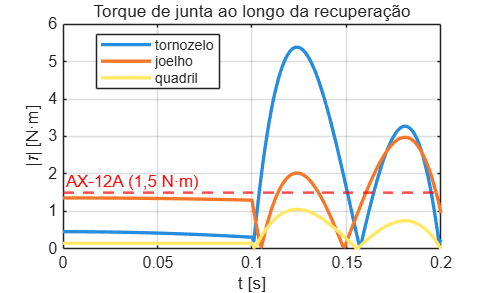

    Cx_c = quintico_coef(pos1(1), vel1(1), acc1(1), alvo0(1), 0, 0, T_cor_ok);
    Cy_c = quintico_coef(pos1(2), vel1(2), acc1(2), alvo0(2), 0, 0, T_cor_ok);
    f3_c = Cx_c(1) + Cx_c(2)*s + Cx_c(3)*s^2 + Cx_c(4)*s^3 + Cx_c(5)*s^4 + Cx_c(6)*s^5;
    g3_c = Cy_c(1) + Cy_c(2)*s + Cy_c(3)*s^2 + Cy_c(4)*s^3 + Cy_c(5)*s^4 + Cy_c(6)*s^5;

    tv3_c = 0:P.dt:T_cor_ok;
    [Q3_c, ~, DDQ3_c] = cinematica_cm(P, s, f3_c, g3_c, tv3_c, Q2(:,end));

    % ── linha do tempo completa: perturbação + retorno ───────────────────
    tv_c  = [tv2,   t_reac + tv3_c(2:end)];
    Q_c   = [Q2,    Q3_c(:,2:end)];
    DDQ_c = [DDQ2,  DDQ3_c(:,2:end)];

    % ── mesma dinâmica inversa da seção anterior ─────────────────────────
    TAU_c = zeros(3, numel(tv_c));
    for k = 1:numel(tv_c)
        lambda_k   = (f_phi_din_q(Q_c(:,k)).') \ (QA - P.M_mat*DDQ_c(:,k));
        TAU_c(:,k) = -lambda_k(7:9);
    end


    tau_pico_c = max(abs(TAU_c), [], 2);
    fprintf('T_cor = %.2f s  ->  |tau| max = [%6.3f %6.3f %6.3f] N·m\n', ...
        T_cor_ok, tau_pico_c);

    achou = all(tau_pico_c < P.tau_max);
end

if ~achou
    error('Nenhum T_cor até %.2f s respeitou P.tau_max = %.2f N·m.', T_busca_max, P.tau_max);
end

fprintf('\nMenor tempo de correção dentro de %.2f N·m:  T_cor = %.2f s\n', P.tau_max, T_cor_ok);
for j = 1:3
    fprintf('   %-10s %7.4f N·m\n', nomes{j}, tau_pico_c(j));
end

fig_ok = figure('Color', 'w');
try, theme(fig_ok, 'light'); catch, end
hold on; grid on; box on;

for j = 1:3
    plot(tv_c, abs(TAU_c(j,:)), 'LineWidth', 2, 'Color', cor(j,:));
end
yline(P.tau_max, '--r', 'AX-12A (1,5 N·m)', 'LineWidth', 1.5, ...
    'LabelHorizontalAlignment', 'left');
xline(t_reac, ':k', 'início da correção', 'LineWidth', 1.2);

ylim([0, 1.15*P.tau_max]);
xlabel('t [s]'); ylabel('|\tau| [N·m]');
legend(nomes_leg, 'Location', 'best');
title(sprintf('Torque com T_{cor} = %.2f s', T_cor_ok), 'FontWeight', 'normal');

% animar robô
Q_junta_c = P.T_junta * Q_c([3 6 9], :);
anima_robo(P, Q_junta_c, tv_c, 'animacao_cm.gif');

T_cor = 0.10 s  ->  |tau| max = [ 4.362  2.573  0.843] N·m
T_cor = 0.11 s  ->  |tau| max = [ 3.885  2.354  0.741] N·m


## Funções

function C = quintico_coef(p0, v0, a0, pT, vT, aT, T)
%QUINTICO_COEF  Coeficientes [c0..c5] de c0+c1*s+...+c5*s^5, com posição,
%  velocidade e aceleração prescritas em s=0 e s=T.

Nenhum T_cor até 1.00 s respeitou P.tau_max = 1.50 N·m.

c0 = p0;  c1 = v0;  c2 = a0/2;
A = [T^3 T^4 T^5; 3*T^2 4*T^3 5*T^4; 6*T 12*T^2 20*T^3];
b = [ pT - (c0+c1*T+c2*T^2) ;
    vT - (c1+2*c2*T)      ;
    aT - 2*c2             ];
C = [c0; c1; c2; A\b];
end

% descrição de funções

% a = simplify(a) -  (Symbolic Math Toolbox) pega uma expressão simbólica e tenta reescrevê-la numa forma algebricamente equivalente mais enxuta
%                     sin(a)*cos(b) - cos(a)*sin(b)  = sin(a-b)